clear all
close all;
clc;
% Tf Generation
m1=1;
m2=1;
k1=(86+1)/15;
b2=k1;
k2=(1+86)/100;
b1=k2;
k3=k2/2;
A=[0 1 0 0;
    -(k1+k3)/m1 -b1/m1 k3/m1 0;
    0 0 0 1;
    k3/m2 0 -(k2+k3)/m2 -b2/m2];
B=[0 ;1/m1 ;0 ;0]; 
C=[1 0 1 0]; 
D=0;
[b,a]= ss2tf(A,B,C,D);
sys=tf(b,a);
fb = bandwidth(sys);
Ts=0.05*2*pi/fb; %seconds
sysd = c2d(sys, Ts,'zoh');
[c,d]=tfdata(sysd,'v');

N_samples=500;
t=0:Ts:Ts*N_samples;
tt=size(t,2);
%%u=[0 0 0 0 ones(1,tt-5)];
noise=[0,0,0,0,.01*randn(1,tt-5)];
u=noise-mean(noise)

u =     0.0006    0.0006    0.0006    0.0006   -0.0145    0.0043   -0.0087   -0.0080    0.0023   -0.0063    0.0006    0.0015    0.0095   -0.0117   -0.0135    0.0064    0.0019   -0.0113   -0.0046    0.0229   -0.0000   -0.0101    0.0010    0.0127    0.0013   -0.0094    0.0058   -0.0203    0.0100   -0.0086    0.0089   -0.0066   -0.0027    0.0075    0.0129   -0.0225    0.0110    0.0046    0.0019   -0.0010    0.0075    0.0036   -0.0012    0.0100    0.0051   -0.0039    0.0109   -0.0069    0.0049   -0.0137


%%u=u+noise;
%%u=noise
num=c

num =          0    0.0040   -0.0024   -0.0038    0.0023


den=d

den =     1.0000   -3.4552    4.4764   -2.5652    0.5445


dd=[d(1,2:5)]

dd =    -3.4552    4.4764   -2.5652    0.5445


init=[dd,c]

init =    -3.4552    4.4764   -2.5652    0.5445         0    0.0040   -0.0024   -0.0038    0.0023


% Sampling
y(1)=0;
y(2)=0;
y(3)=0;
y(4)=0;
%%thetainitial=
for temp=5:N_samples
    y(temp)=[-(y(temp-1:-1:temp-4)),(u(temp:-1:temp-4))]*(init');
end
 
Y=y(1:end)';

## RLS

p(:,:,1)=10^5*eye(8);
p(:,:,2)=p(:,:,1);
p(:,:,3)=p(:,:,1);
p(:,:,4)=p(:,:,1);

theta_hat(:,1)=[0;0;0;0;0;0;0;0];
theta_hat(:,2)=theta_hat(:,1);
theta_hat(:,3)=theta_hat(:,1);
theta_hat(:,4)=theta_hat(:,1);

k(:,1)=zeros(8,1);
k(:,2)=zeros(8,1);
k(:,3)=zeros(8,1);
k(:,4)=zeros(8,1);

for temp=5:N_samples
    
    phi(:,temp)=[-(y(temp-1:-1:temp-4)),(u(temp-1:-1:temp-4))]';
    p(:,:,temp)=p(:,:,temp-1)-p(:,:,temp-1)*phi(:,temp)*(1+phi(:,temp-1)'*p(:,:,temp-1)*phi(:,temp))*phi(:,temp)'*p(:,:,temp-1);
    %%k(:,temp)=p(:,:,temp)*phi(:,temp)
    %%theta_hat(:,temp)=theta_hat(:,temp-1)+k(:,temp)*(y(temp)-phi(:,temp)'*theta_hat(:,temp-1))
    
end

phi=[];

phi(1,:)=[0 0 0 0 0 0 0 0];
phi(2,:)=[0 0 0 0 0 0 0 0];
phi(3,:)=[0 0 0 0 0 0 0 0];
phi(4,:)=[0 0 0 0 0 0 0 0];
for temp=5:N_samples
    phi(temp,:)=[-(y(temp-1:-1:temp-4)),(u(temp-1:-1:temp-4))];
end

theta_hat=((phi'*phi)^-1)*phi'*Y;
normpara=norm(theta_hat-[den(2:end),num(2:end)]')

normpara = 3.2143e-06

normy=norm(Y-phi*theta_hat)

normy = 4.5091e-10

rmsd=sqrt(sum(((theta_hat-[den(2:end),num(2:end)]').^2)/8))

rmsd = 1.1364e-06

error=[normpara;rmsd;normy]

error = 	1.0e+-5 *

    0.3214
    0.1136
    0.0000


sysdd=tf([0,theta_hat(5:end)'],[1,theta_hat(1:4)'],Ts);
theta_hat

theta_hat =    -3.4552
    4.4764
   -2.5652
    0.5445
    0.0040
   -0.0024
   -0.0038
    0.0023


disp([den(2:end),num(2:end)]')

   -3.4552
    4.4764
   -2.5652
    0.5445
    0.0040
   -0.0024
   -0.0038
    0.0023



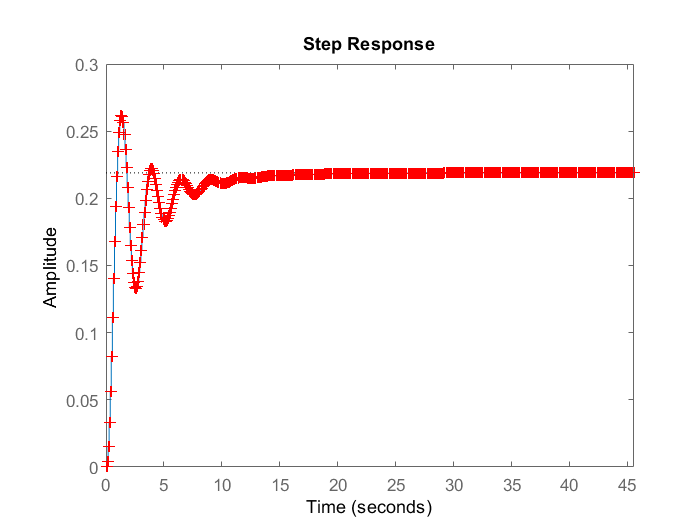

figure
step(sysdd,t)
hold on
step(sysd,t,'r+')

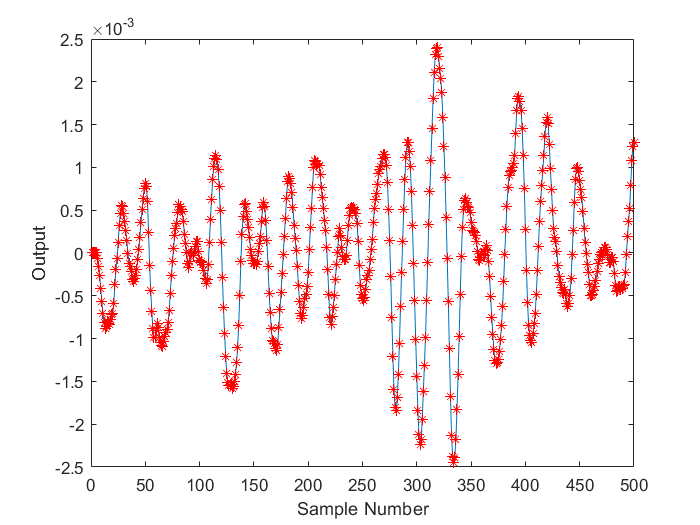

figure
plot(Y)
hold on
plot(phi*theta_hat,'r*')
xlabel('Sample Number')
ylabel('Output')